# Introduction to Synthetic Aperture Radar Using Python and MATLAB

## by Andy Harrison - © 2022 Artech House

### Example 3.4.2 Range Profile - Backhoe

## Calculate the range profile from the matched filter output

% Load the signature file
load('backhoe_el000_az350to100.mat');

% Set the window type
window_type = 'Hanning';

% Set the number of frequencies
nf = 261;

% Display the bandwidth (MHz)
fprintf('Bandwidth = %f\n', (FGHz(nf) - FGHz(1)) * 1e9 / 1e6);

Bandwidth = 3004.761414



% Get the index for data with azimuth of 360 degrees
index = find(AZ == 360);

% Set the data 
signal_vv = VV(1:nf, index);
signal_hh = HH(1:nf, index);
signal_hv = HV(1:nf, index);


% Get the window coefficients
switch window_type
    case 'Hanning'
        coefficients = hanning(nf);
    case 'Hamming'
        coefficients = hamming(nf);
    otherwise
        coefficients = ones(nf, 1);
end

% Apply the selected window
signal_vv = signal_vv .* coefficients';
signal_hh = signal_hh .* coefficients';
signal_hv = signal_hv .* coefficients';

% Reconstruct the image
rp_vv = fftshift(ifft(signal_vv, 4096));
rp_hh = fftshift(ifft(signal_hh, 4096));
rp_hv = fftshift(ifft(signal_hv, 4096));

% Set up the time array (s)
T = 1e-9 / (2 * (FGHz(2) - FGHz(1)));
t = linspace(-0.5*T*3e8, 0.5*T*3e8, 4096); 

% Normalize the profiles to HH polarization
factor = max(abs(rp_hh));

## Plot the results

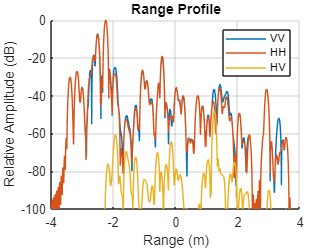

figure; hold on;
plot(t, 20 * log10(abs(rp_vv)./factor));
plot(t, 20 * log10(abs(rp_hh)./factor));
plot(t, 20 * log10(abs(rp_hv)./factor));

% Set the legend
legend({'VV', 'HH', 'HV'})

% Set the plot title and labels
title('Range Profile')
xlabel('Range (m)')
ylabel('Relative Amplitude (dB)')
grid on;

% Set x- and y-axis limits
xlim([-4, 4])
ylim([-100, 0])